# Znajdowanie parametrów teczówki – 

# operator różniczkowo-całkowy Daugmana

Zuzanna Rudnicka

249533

Antoni Bezdzietny

249327

#### Przygotowanie ścieżki do zdjęcia.

clear all;
addpath("scripts\daugman\")
set_default = true;
            
image_folder = "database/image_ir/";
eye         = "007" ;
eye_side    = "1";
eye_variant = "1";
image_path = strcat(image_folder,eye,"/",eye_side,"/",eye,"_",eye_side,"_",eye_variant,".bmp");

#### Wczytanie zdjęcia.

img_gray    = imread(image_path); 

#### Wyświetlenie przetwarzanych obrazów w odcieniach szarości.

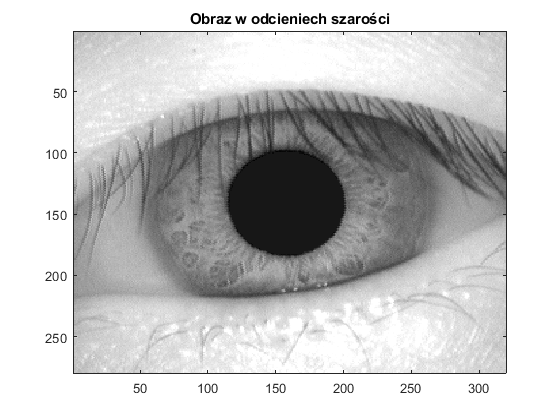

imagesc(img_gray);
title("Obraz w odcieniech szarości");
colormap("gray");

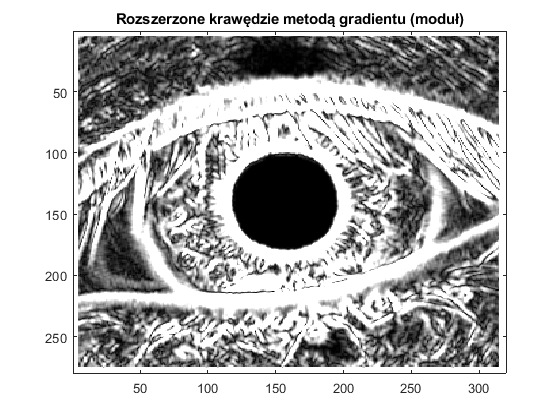

[h_edge, v_edge, image_edge] = FindEdges(img_gray);

image(image_edge);
title("Rozszerzone krawędzie metodą gradientu (moduł)");